# Training Unit 5: ODE numerical solver

Fink Lucas / Teichtmeister Marcus, 28.10.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Derivation of the Analytical Solution of the Ordinary Differential Equation

The following ODE is given:


$$\frac{\textrm{dy}}{\textrm{dt}}=-\frac{y}{\tau \;}$$


First, the equation is multiplied by $\textrm{dt}$ and divided by $y$.


$$\frac{1}{y}\textrm{dy}=-\frac{1}{\tau \;}\textrm{dt}$$


Then integrated on both sides.


$$\int \;\frac{1}{y}\textrm{dy}=-\int \;\frac{1}{\tau \;}\textrm{dt}\to \ln \left(|y|\right)+C_1 =-\frac{t}{\tau \;}+C_2 \to \ln \left(|y|\right)=-\frac{t}{\tau \;}+C$$



$$y=e^{-\frac{t}{\tau \;}+C} =e^C e^{-\frac{t}{\tau \;}}$$


Which gives the function:


$$y=y_0 \;e^{-\frac{t}{\tau \;}}$$
    

## Implementing the Analytical Solution

Initalizing the inital condition and the Parameters for solving the DEQ

PARAMETERS.y_0     = 1;
PARAMETERS.t_0     = 0;
PARAMETERS.t_final = 10;
PARAMETERS.h       = 1;
PARAMETERS.tau     = 2;

Calculating and plotting the analytical solution

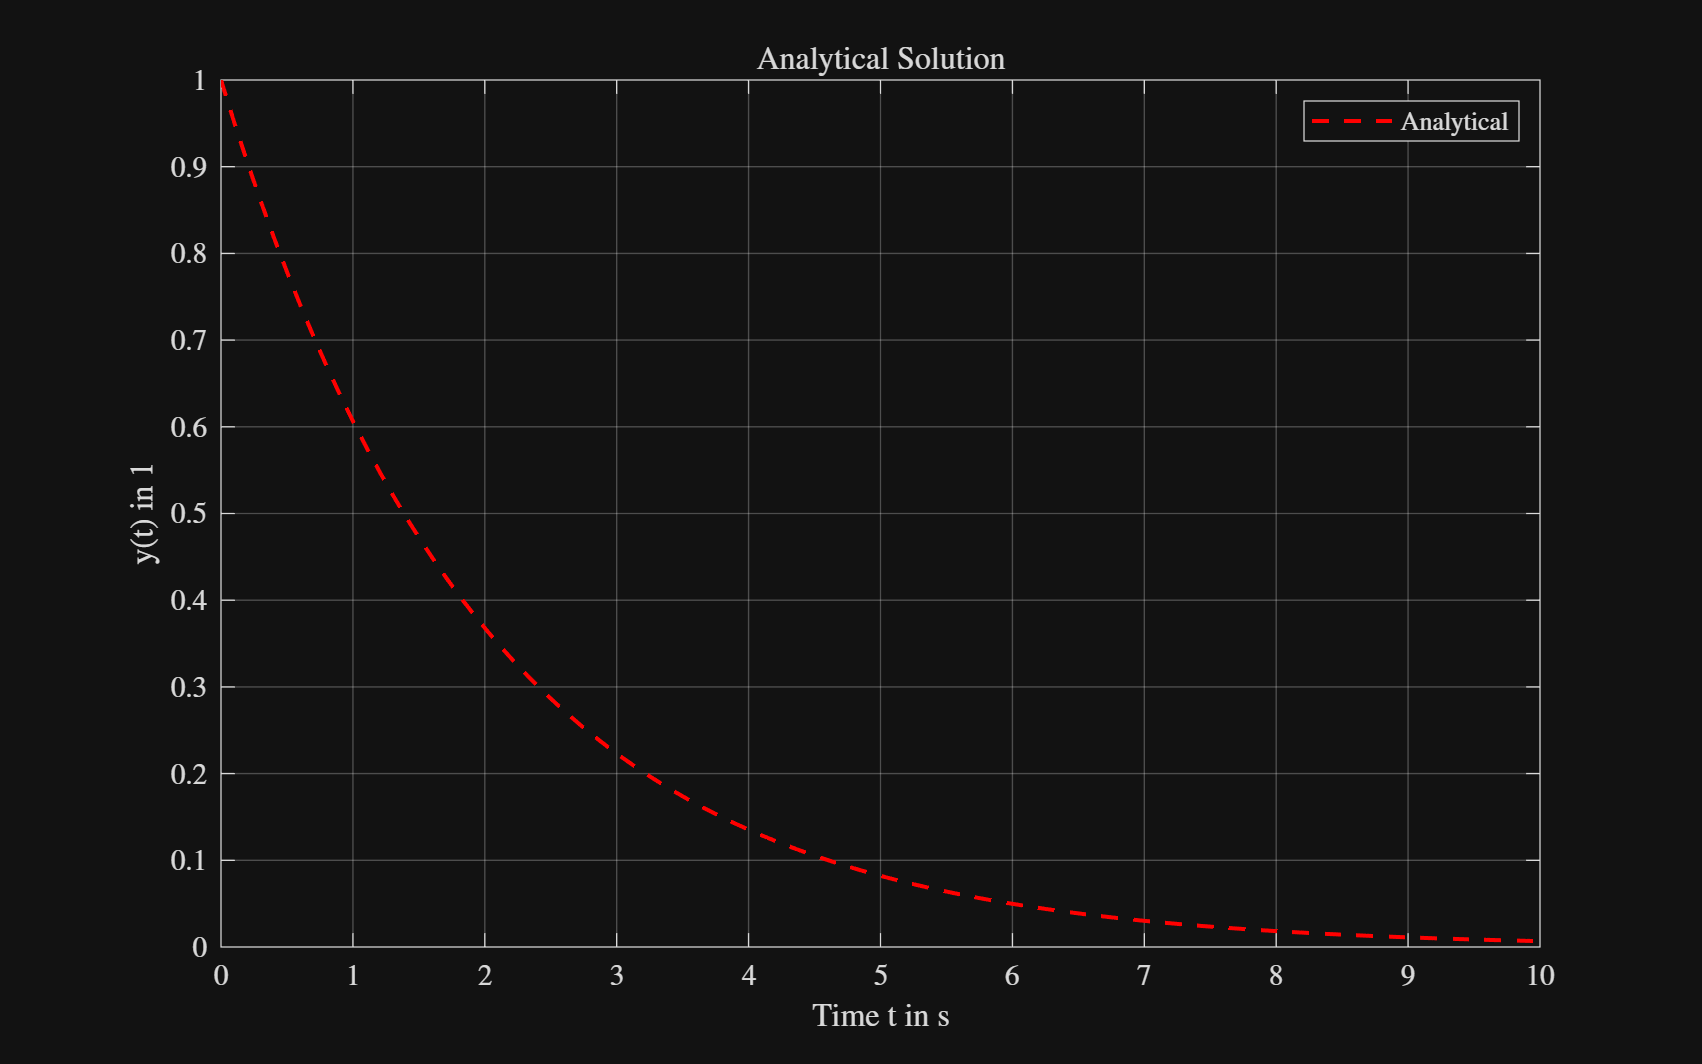

t = linspace(PARAMETERS.t_0, PARAMETERS.t_final, 100); 

% calculating the analytical solution using an external function
y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

%% Plotting the analytical solution
figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])

plot(t, y_exact, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
title('Analytical Solution');
xlabel('Time t in s');
ylabel('y(t) in 1');
grid on;
legend('Location','northeast');

The result resembles the negative exponential function (exponential decay). 

- Since the exponent -t/tau is negative and y_0 = 1 is positive, the function starts at y(0) = 1 and, with increasing t, monotonically decreases to zero.

clearvars -except PARAMETERS

## Implementing the Numerical Solution

The numerical solution is implemented using the Forward Euler Method which is defined as:


$$y_{k+1} =y_k +h\cdot f\left(t_k ,y_k \right)$$


The numerical solver is also implemented in an external function, which receives all previously defined PARAMETERS. The function returns the time and the numerical solution

[t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

To better display the calculation results, the data is stored in a Matlab table

Results = table(t(:), y_num(:), y_exact(:), 'VariableNames', {'Time','y_Numerical','y_Analytical'});

Calculating and plotting the numerical solution versus analytical 

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2,1);

ax1 = nexttile;
yyaxis left
plot(t, y_num, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Numerical');
hold on
plot(t, y_exact, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
ylabel('y(t) in 1');
legend('Location','northeast');
hold on

The numerical solution almost resembles the anlytical solution, although a significant error can be seen due to the low step size.

### Investigation of the Error between Analytical and Numerical Solution

An additional external function is implemented, which receives the solution of the numerical and analytical calculation and returns:

- Absolute Error

- Relative Error

- Mean Total Error

- Mean Relative Error

[abs_error, mean_abs_error, rel_error, mean_rel_error] = computer_error(y_exact, y_num);

The absolute error is added to the existing plot and the relative error is displayed in an additional tile

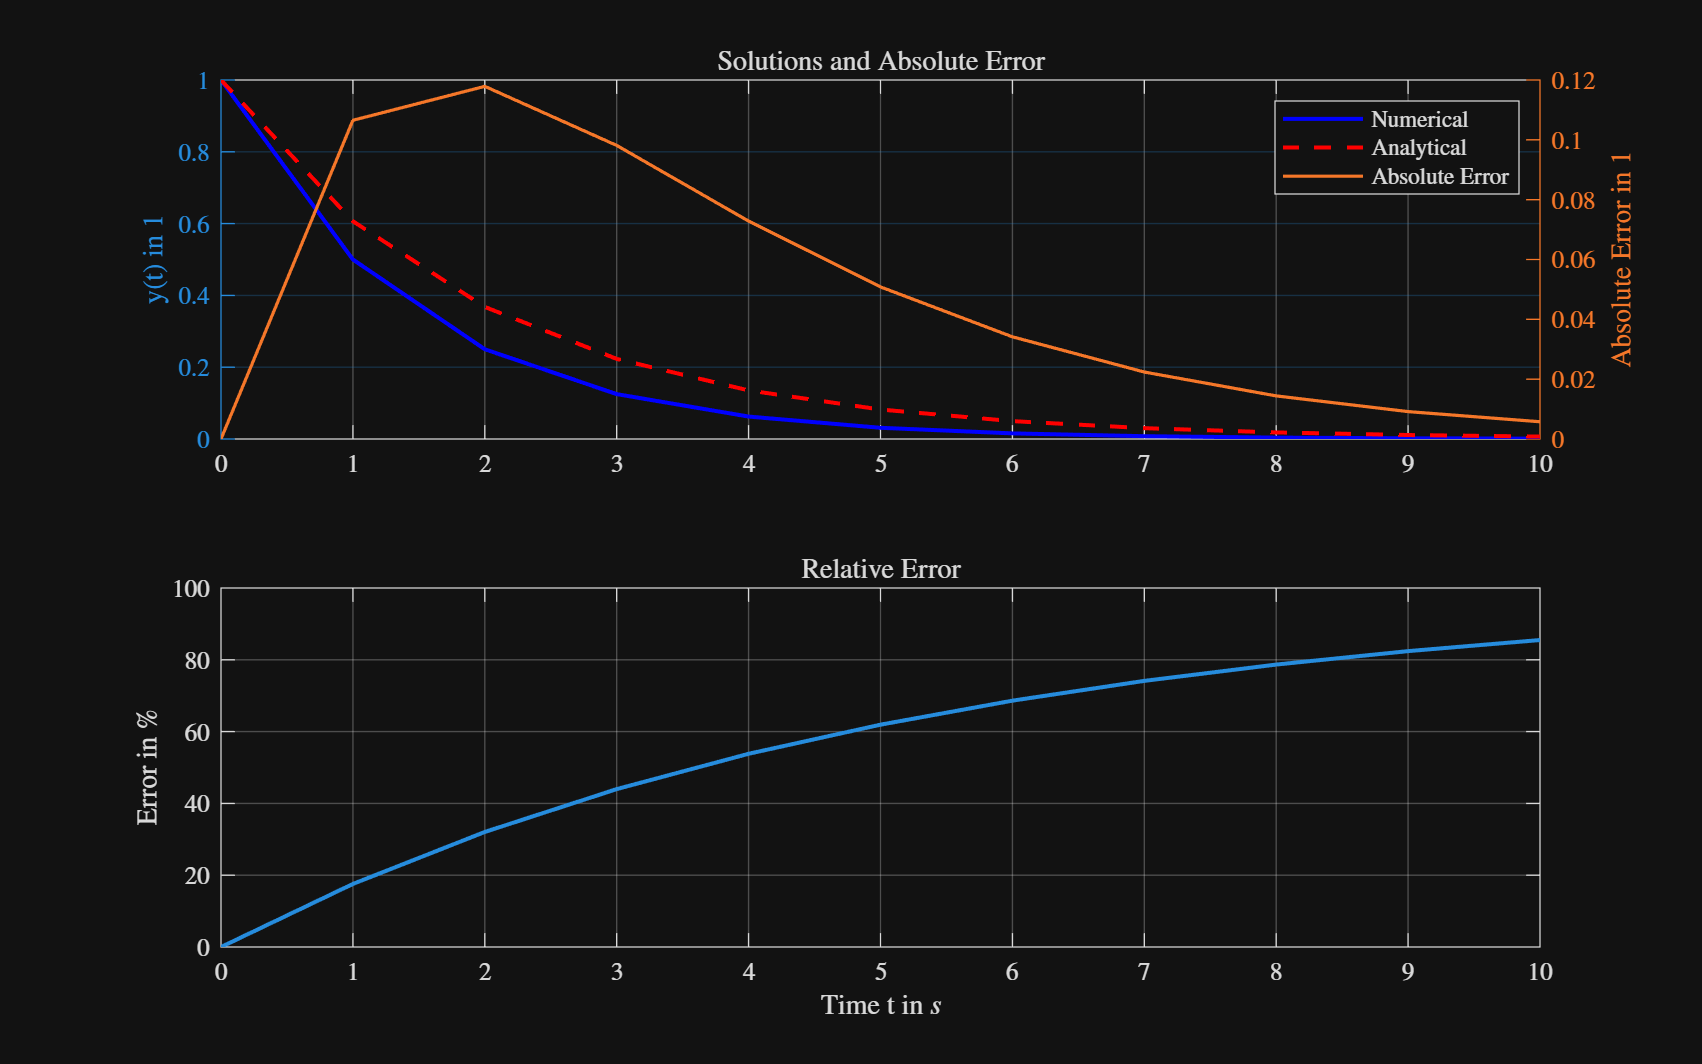

yyaxis right
plot(t, abs_error, 'LineWidth', 1.2, 'DisplayName', 'Absolute Error');
ylabel('Absolute Error in 1');
grid on
title('Solutions and Absolute Error');

ax2 = nexttile;
plot(t, rel_error, 'LineWidth', 1.5, 'DisplayName', 'Relative Error');
xlabel('Time t in $s$');
ylabel('Error in $\%$');
grid on
title('Relative Error');

linkaxes([ax1, ax2],'x');

Displaying the Mean Total Error and tje Mean Relative Error:

disp(['Mean relative error: ', num2str(mean_rel_error), '%']);

Mean relative error: 54.4251%


disp(['Mean absolute error: ', num2str(mean_abs_error)]);

Mean absolute error: 0.048371


## Trying out different step sizes + Investigation of the behaviour of the solver

First, we examine how the mean error changes over different step sizes $e\left(h\right)$

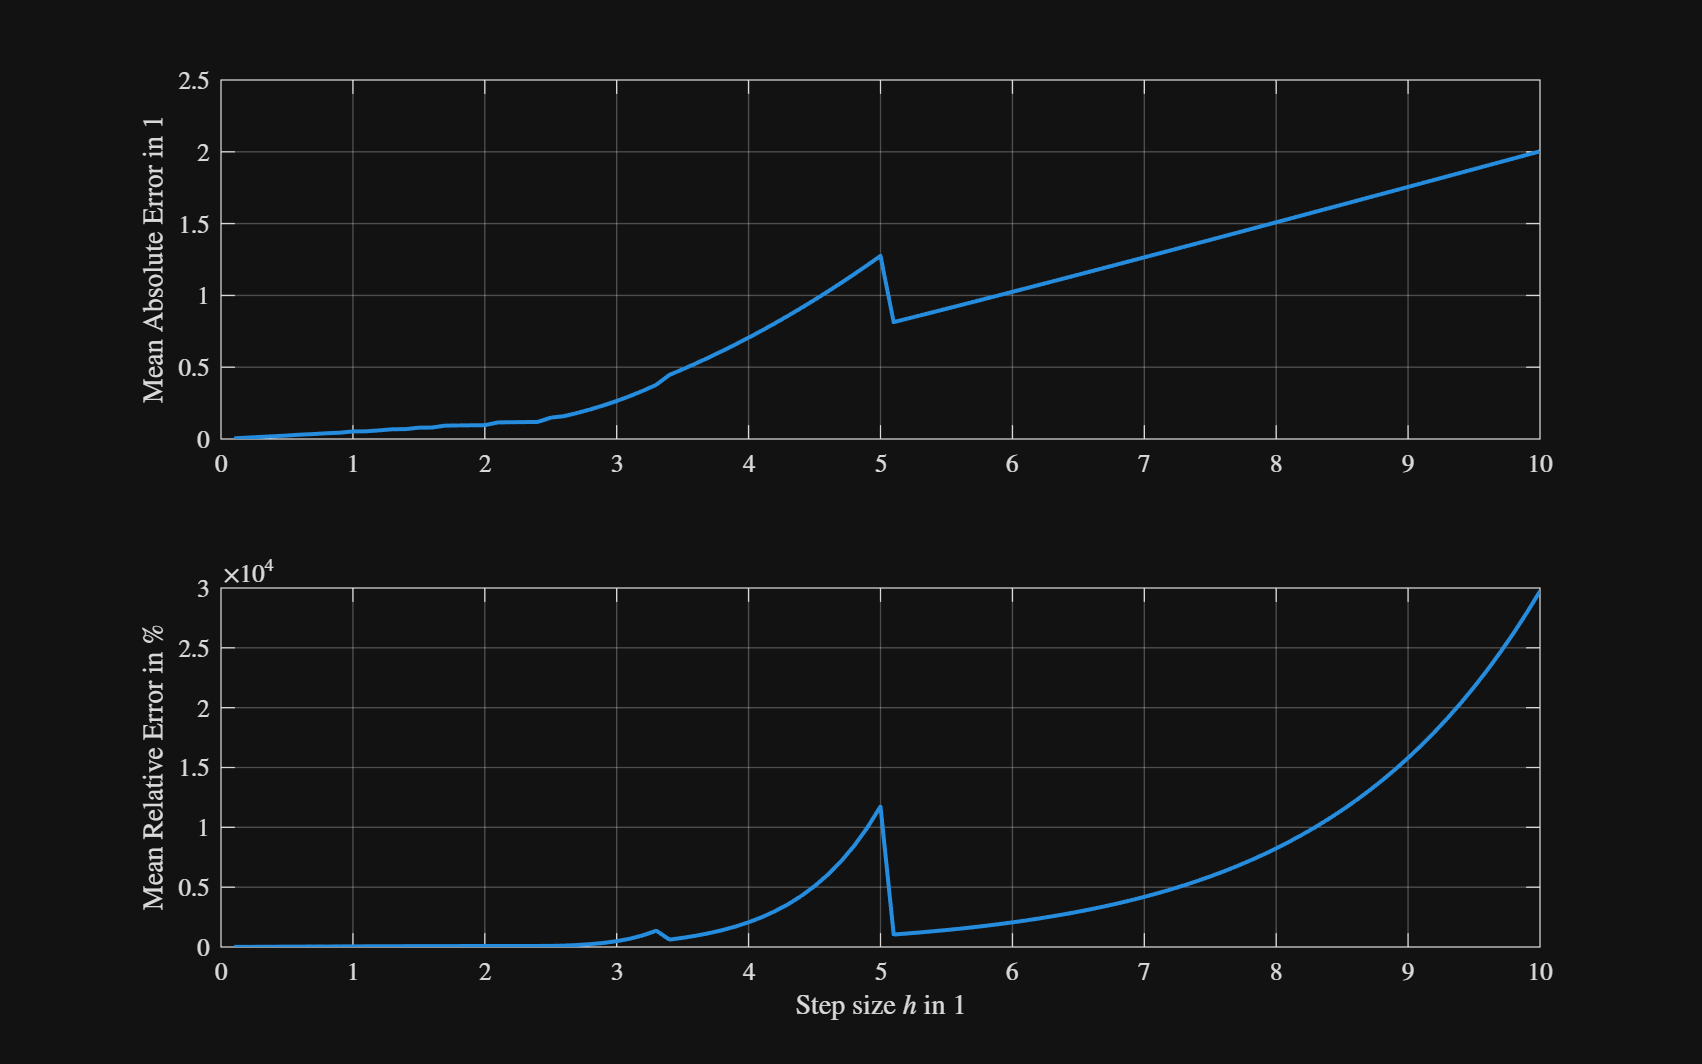

% Step sizes to test
h_values = linspace(0.1,10,100);

% Preallocate vectors for mean errors
mean_abs_errors = zeros(size(h_values));
mean_rel_errors = zeros(size(h_values));

% Loop over each step size
for i = 1:length(h_values)
    h = h_values(i);

    % Numerical solution
    [t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, h, PARAMETERS.t_0, PARAMETERS.t_final);

    % Exact solution
    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

    [~, mean_abs_error, ~, mean_rel_error] = computer_error(y_exact, y_num);

    mean_abs_errors(i) = mean_abs_error;
    mean_rel_errors(i) = mean_rel_error;
end

% Plot mean errors vs step size
figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2,1)
pl1 = nexttile;
plot(h_values, mean_abs_errors, 'LineWidth', 1.5, 'DisplayName', 'Mean Absolute Error');
ylabel('Mean Absolute Error in 1');
grid on;

pl2 = nexttile;
plot(h_values, mean_rel_errors, 'LineWidth', 1.5, 'DisplayName', 'Mean Relative Error');
xlabel('Step size $h$ in 1');
ylabel('Mean Relative Error in $\%$');
grid on;

For small step sizes $h\le 3$:

- **Observation:** The error curves show that the mean errors **increase gradually** as h increases and As h approaches zero, the error also approaches zero.

- Additionally the sharp drop at $h\approx 5\;$could be further investigated

Next up, we investigate the stability of the Forward Euler Solver for different steo sizes h. Theoretical Limit: For the ODE  $\frac{\textrm{dy}}{\textrm{dt}}=-\frac{y}{\tau \;}$ with $\tau =2$, the Forward Euler method is only stable if the step size h satisfies the condition: $h\le 2\tau$

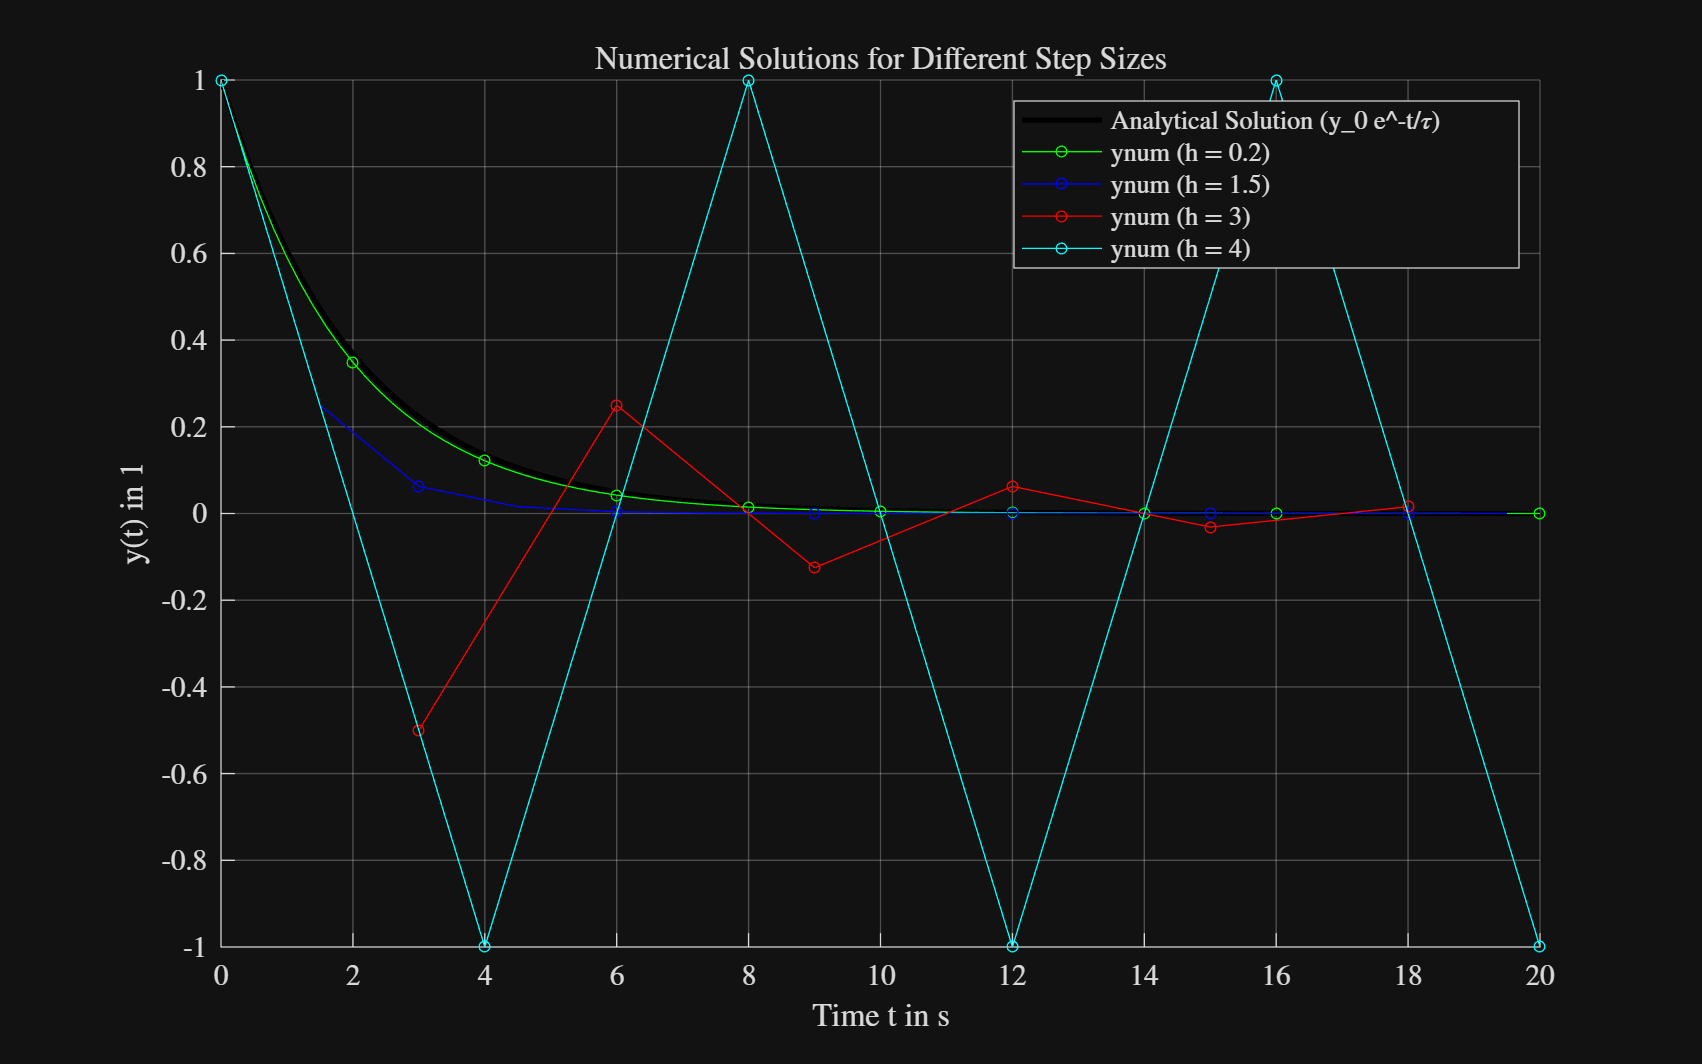

h_investigation = [0.2, 1.5, 3, 4]; % [Accurate, Stable/Inaccurate, Stable/Inaccurate, Unstable]
PARAMETERS.t_final_long = 20;       % increasing the time, to better see if the solution converges

%% Numerical Solution for Representative Step Sizes
figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
hold on;
title('Numerical Solutions for Different Step Sizes');
xlabel('Time t in s');
ylabel('y(t) in 1');

% 1. Plotting Analytical Solution as Reference
t_ref = linspace(PARAMETERS.t_0, PARAMETERS.t_final_long, 100);
y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t_ref);
plot(t_ref, y_exact, 'k-', 'LineWidth', 2, 'DisplayName', 'Analytical Solution (y_0 e^{-t/\tau})');

% 2. Plotting Numerical Solutions
colors = {'g', 'b', 'r', 'c'}; 

for j = 1:length(h_investigation)
    h = h_investigation(j);
    
    [t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, h, PARAMETERS.t_0, PARAMETERS.t_final_long);

    plot(t, y_num, ['-' colors{j} 'o'], 'MarkerSize', 4, ...
         'MarkerIndices', 1:ceil(1/h*2):length(t), ... 
         'DisplayName', ['ynum (h = ' num2str(h) ')']);
end
legend('Location', 'ne');
grid on;
hold off;

- For $h=4$, the numerical solution shows oscillatory instability  and for $h>4$ it would grow exponentially instead of decaying to zero

clearvars -except PARAMETERS

## Implementing a second solver

The second solver is implemented using the Mid-Point (MP) method, which is a particular case of Runge-Kutta second order method and is defined as:


$$k_1 =f\left(t_k ,y_k \right)$$



$$k_2 =f\left(t_k +\frac{h}{2},y_k +k_1 \cdot \frac{h}{2}\right)$$



$$y_{k+1} =y_k +h\cdot k_2$$


Additionally, the Mid-Point Method is compared to the Euler's Forward Method and the analytical solution

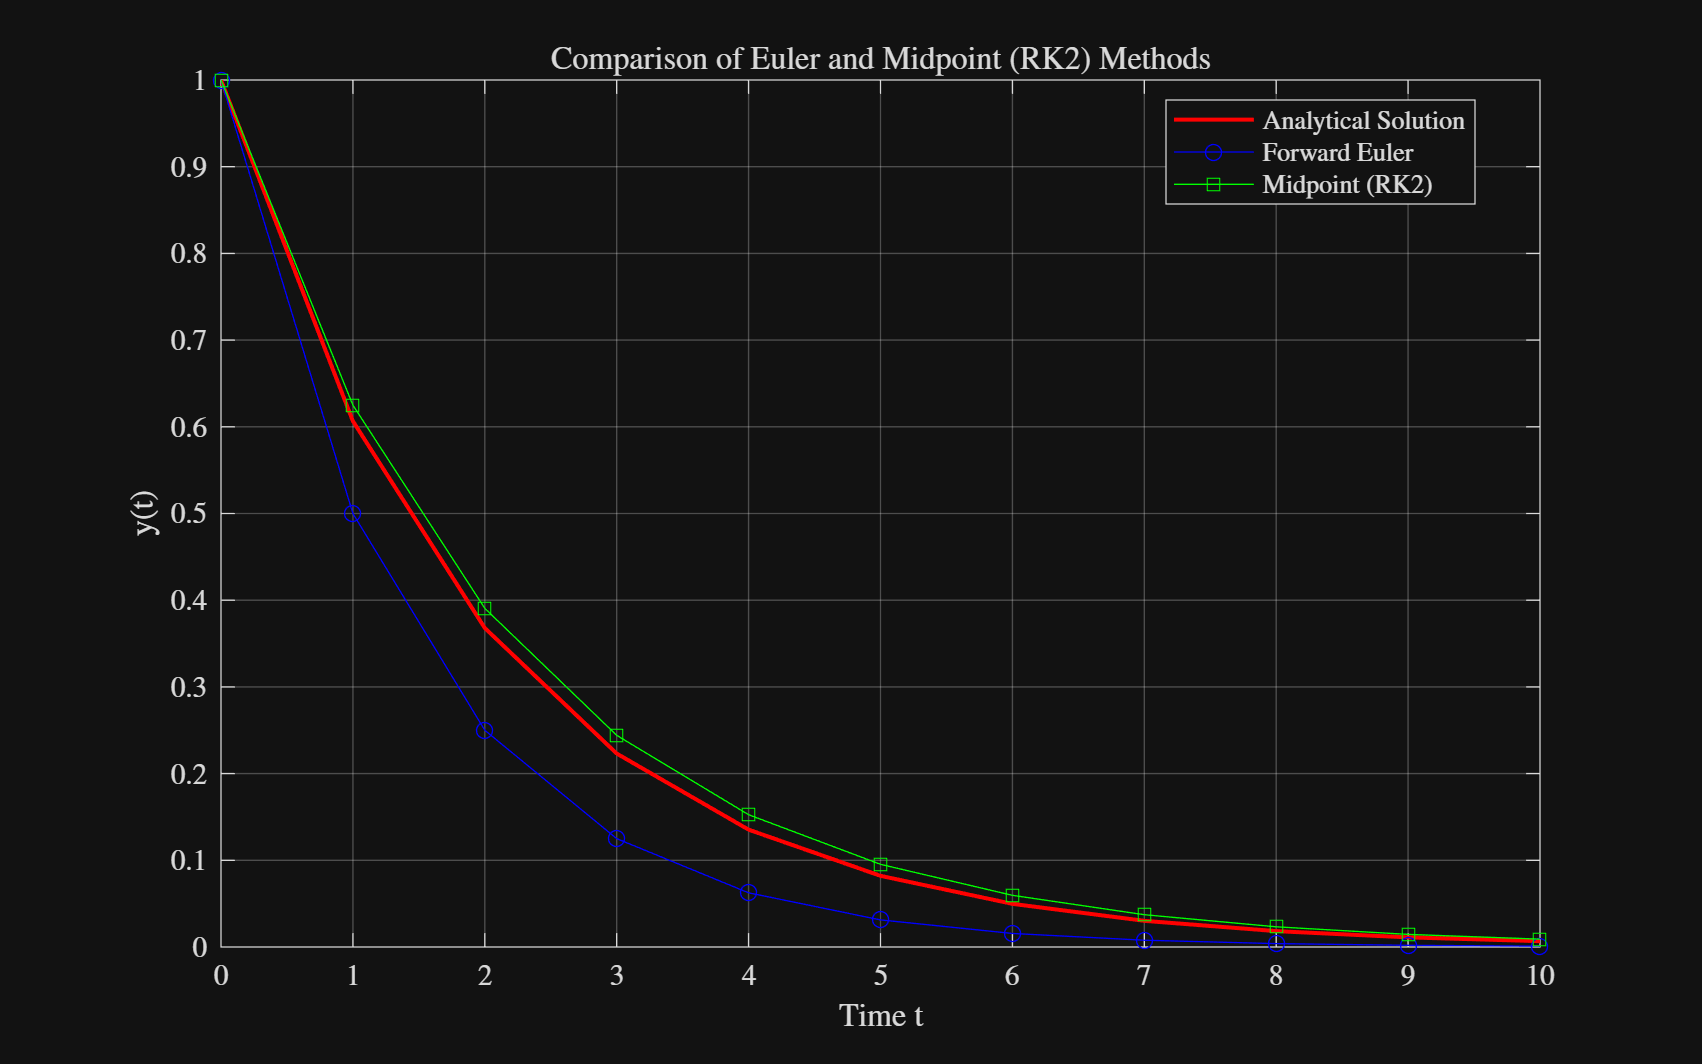

[t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

[t, y_mid] = midpoint_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
plot(t, y_exact, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Analytical Solution');
hold on;
plot(t, y_num, 'bo-', 'DisplayName', 'Forward Euler');
plot(t, y_mid, 'gs-', 'DisplayName', 'Midpoint (RK2)');
xlabel('Time t');
ylabel('y(t)');
title('Comparison of Euler and Midpoint (RK2) Methods');
legend('Location', 'best');
grid on;

As we can see in the graph, the Mid-Point Method resembles the analytical solution much closer than the Euler's Forward Method 

The next plot shows how the error changes when the step size changes again

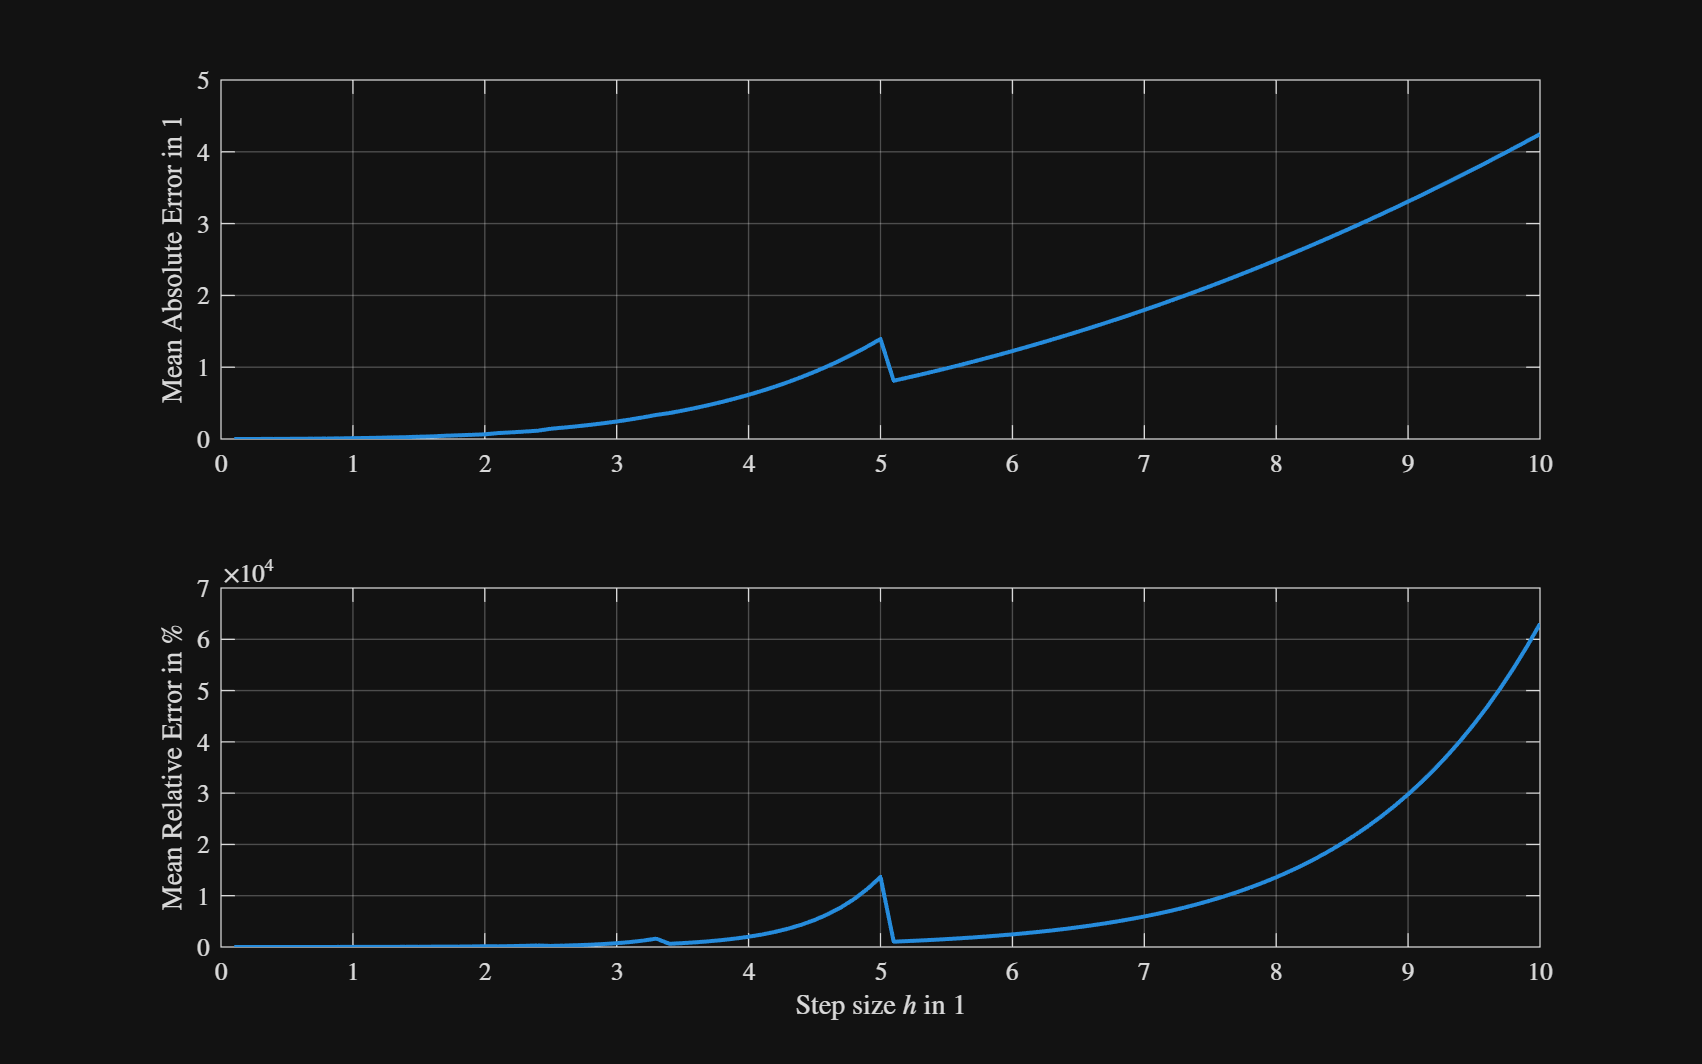

h_values = linspace(0.1,10,100);

% Preallocate vectors for mean errors
mean_abs_errors = zeros(size(h_values));
mean_rel_errors = zeros(size(h_values));

% Loop over each step size
for i = 1:length(h_values)
    h = h_values(i);

    % Numerical solution
    [t, y_mid] = midpoint_solver(PARAMETERS.y_0, PARAMETERS.tau, h, PARAMETERS.t_0, PARAMETERS.t_final);

    % Exact solution
    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

    [~, mean_abs_error, ~, mean_rel_error] = computer_error(y_exact, y_mid);

    mean_abs_errors(i) = mean_abs_error;
    mean_rel_errors(i) = mean_rel_error;
end

% Plot mean errors vs step size
figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2,1)
pl1 = nexttile;
plot(h_values, mean_abs_errors, 'LineWidth', 1.5, 'DisplayName', 'Mean Absolute Error');
ylabel('Mean Absolute Error in 1');
grid on;

pl2 = nexttile;
plot(h_values, mean_rel_errors, 'LineWidth', 1.5, 'DisplayName', 'Mean Relative Error');
xlabel('Step size $h$ in 1');
ylabel('Mean Relative Error in $\%$');
grid on;

If we compare the e(h) from the Mid-Point to the Euler's Forward Message, it can be seen that the error for smaller step sizes is also smaller, but grows much higher for larger step sizes

clearvars -except PARAMETERS

## Adding a step size control to the numerical calcultation

Next, an automatic step size control is implemented. For that the error $\varepsilon$ is calculated. If the local error is greater than the specified tolerance r, the step size is changed.

$h_{\textrm{new}} =\frac{h_{\textrm{old}} \cdot r}{\varepsilon }$ and $\varepsilon =\left|y_{\textrm{kMP}} -y_{\textrm{kEuler}} \right|$

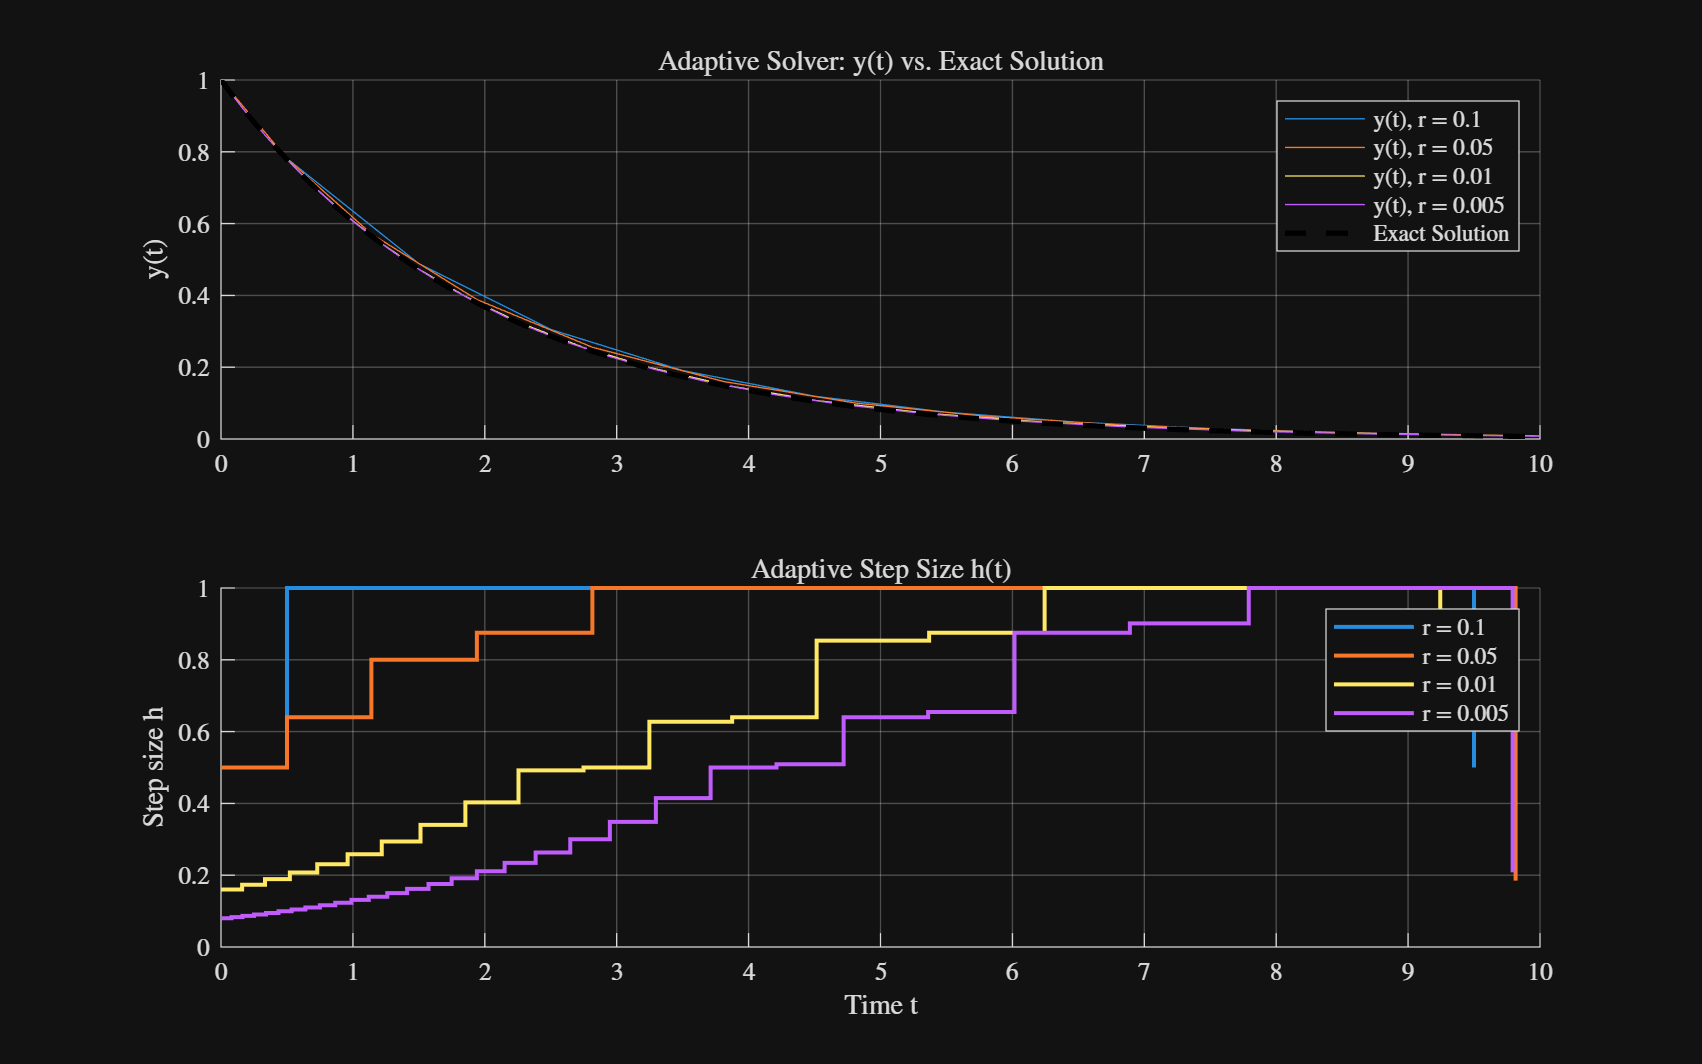

r_values = [0.1 0.05, 0.01, 0.005]; 

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2,1);

nexttile(1); 
hold on; grid on;
title('Adaptive Solver: y(t) vs. Exact Solution');

nexttile(2); 
hold on; grid on;
title('Adaptive Step Size h(t)');
xlabel('Time t');

for r = r_values
    
    [t, y, h_values] = variable_step_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                                            PARAMETERS.t_0, PARAMETERS.t_final, r);

    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

    
    % y(t) Lösung
    nexttile(1);
    plot(t, y, 'DisplayName', ['y(t), r = ', num2str(r)]);
    
    % h(t) Schrittweite
    nexttile(2);
    stairs(t(1:end-1), h_values, 'LineWidth', 1.5, 'DisplayName', ['r = ', num2str(r)]); 

end

nexttile(1);

t_ref = linspace(PARAMETERS.t_0, PARAMETERS.t_final, 500);
y_exact_ref = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t_ref);
plot(t_ref, y_exact_ref, 'k--', 'LineWidth', 2, 'DisplayName', 'Exact Solution', 'HandleVisibility', 'on'); 
ylabel('y(t)');
legend('Location','northeast');


nexttile(2);
ylabel('Step size h');
legend('Location','northeast');

- For all r values, the step size is smallest at $t=0$ and increases over time, because  the solution is steepest early on generating the largest local error $\varepsilon$, which forces the solver to use a small step sizes. 

- Therefore r directly controls the magnitude of h across the entire simulation time.

- For the smallest tolerance (r=0.005), the step size h is extremely small and requiring the highest number of steps for the highest accuracy.

- For the biggest tolerance (r=0.1), the solver immediately jumps to the maximum step size (h=1) after the first few steps.

clearvars -except PARAMETERS

## Additional Task: MATLAB UI

**! Change to Hide Code View !**

PARAMETERS.y_0     = 1;
PARAMETERS.t_0     = 0;
PARAMETERS.t_final = 13;
PARAMETERS.h       = 3.29;
PARAMETERS.tau     = 2;
PARAMETERS.r       =0.091;

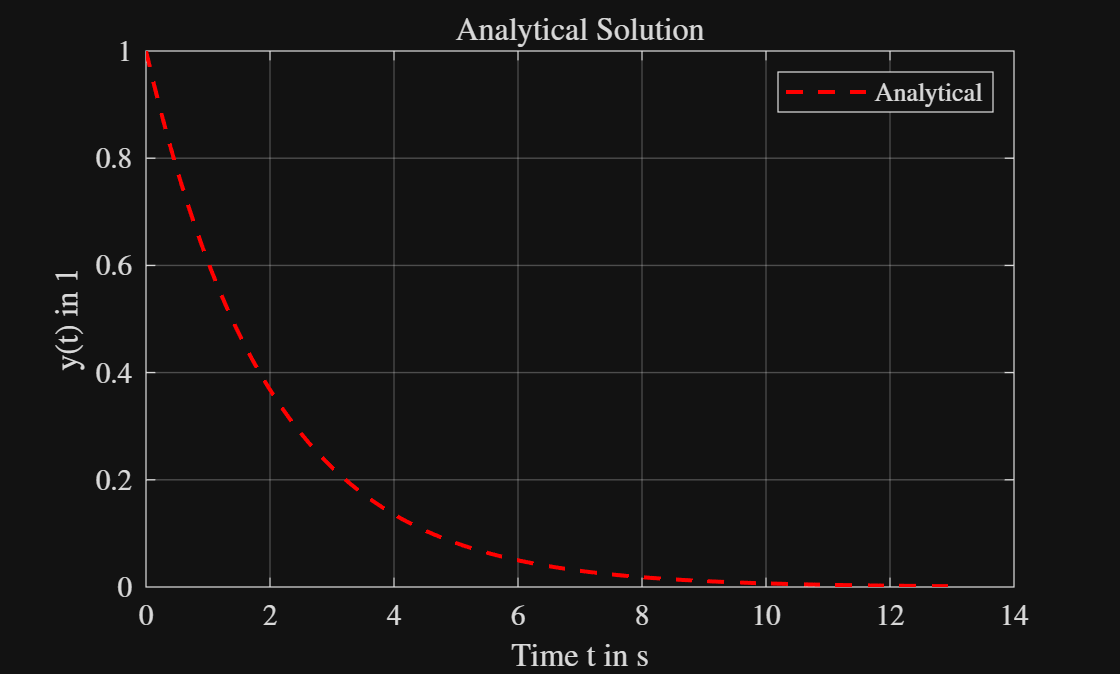

t = linspace(PARAMETERS.t_0, PARAMETERS.t_final, 100); 

% calculating the analytical solution using an external function
y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

%% Plotting the analytical solution
figure;

plot(t, y_exact, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
title('Analytical Solution');
xlabel('Time t in s');
ylabel('y(t) in 1');
grid on;
legend('Location','northeast');

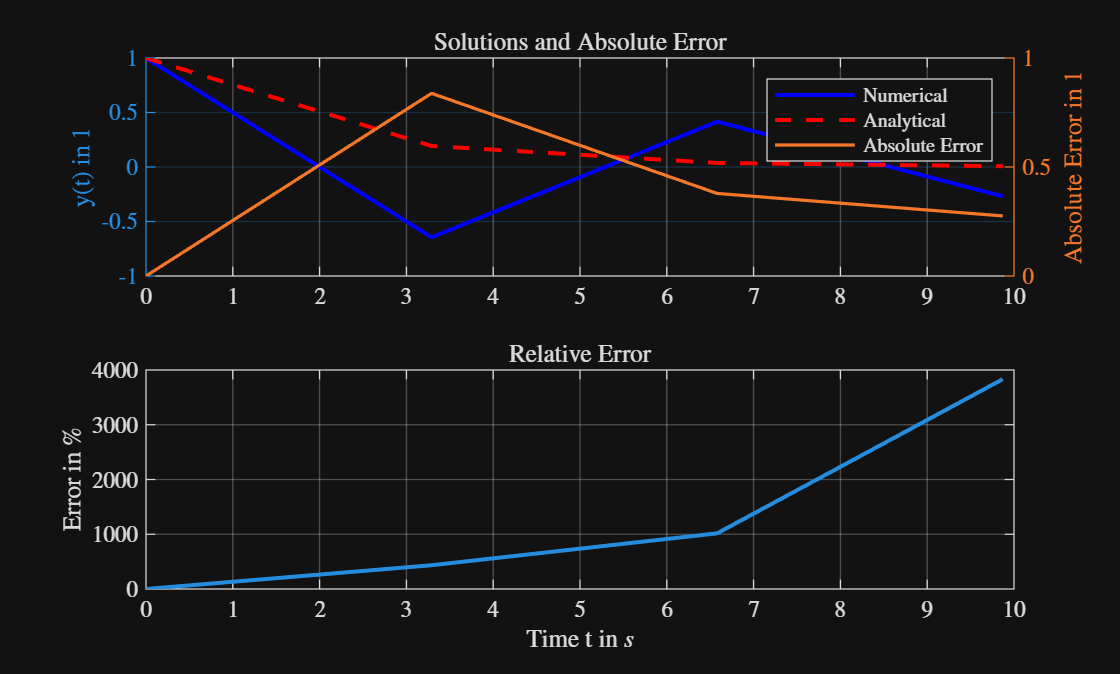

[t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);
figure;
tiledlayout(2,1);

ax1 = nexttile;
yyaxis left
plot(t, y_num, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Numerical');
hold on
plot(t, y_exact, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Analytical');
ylabel('y(t) in 1');
legend('Location','northeast');
hold on
[abs_error, mean_abs_error, rel_error, mean_rel_error] = computer_error(y_exact, y_num);
yyaxis right
plot(t, abs_error, 'LineWidth', 1.2, 'DisplayName', 'Absolute Error');
ylabel('Absolute Error in 1');
grid on
title('Solutions and Absolute Error');

ax2 = nexttile;
plot(t, rel_error, 'LineWidth', 1.5, 'DisplayName', 'Relative Error');
xlabel('Time t in $s$');
ylabel('Error in $\%$');
grid on
title('Relative Error');

linkaxes([ax1, ax2],'x');

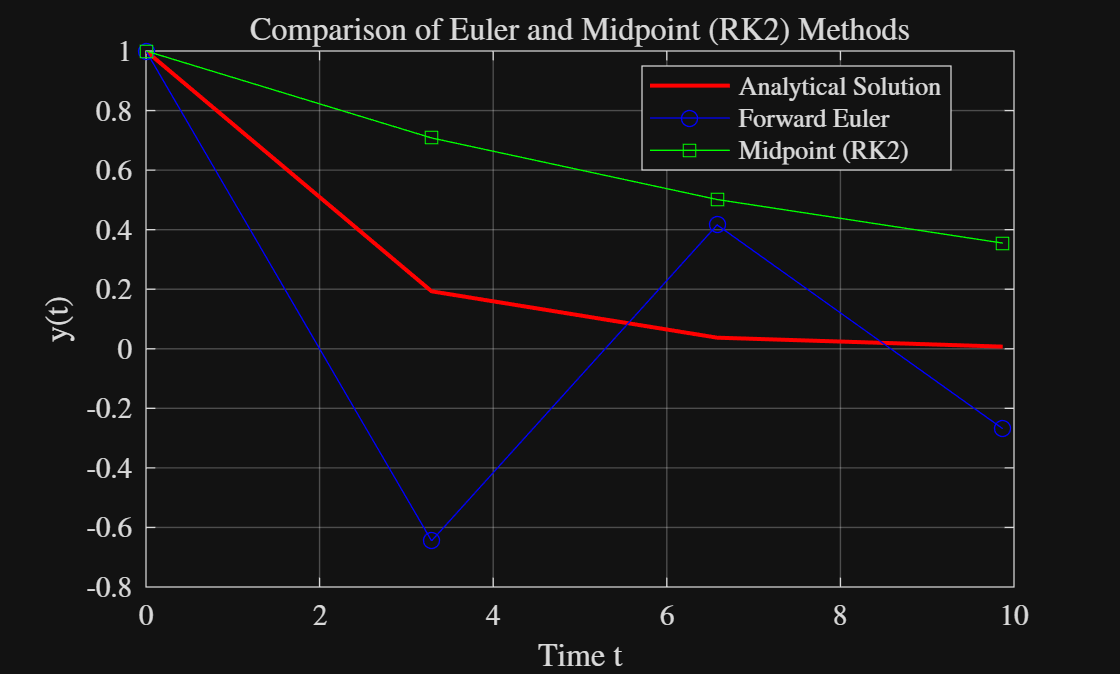

[t, y_num] = num_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

[t, y_mid] = midpoint_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                          PARAMETERS.h, PARAMETERS.t_0, PARAMETERS.t_final);

figure;
plot(t, y_exact, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Analytical Solution');
hold on;
plot(t, y_num, 'bo-', 'DisplayName', 'Forward Euler');
plot(t, y_mid, 'gs-', 'DisplayName', 'Midpoint (RK2)');
xlabel('Time t');
ylabel('y(t)');
title('Comparison of Euler and Midpoint (RK2) Methods');
legend('Location', 'best');
grid on;

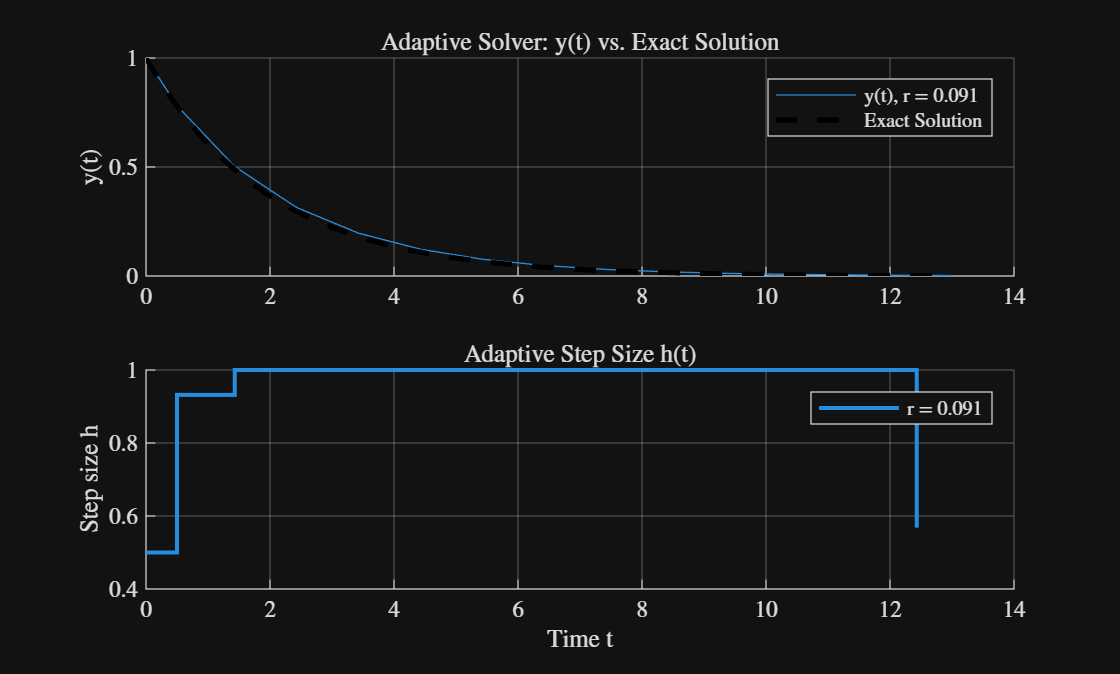

r_values = PARAMETERS.r; 

figure;
tiledlayout(2,1);

nexttile(1); 
hold on; grid on;
title('Adaptive Solver: y(t) vs. Exact Solution');

nexttile(2); 
hold on; grid on;
title('Adaptive Step Size h(t)');
xlabel('Time t');

for r = r_values
    
    [t, y, h_values] = variable_step_solver(PARAMETERS.y_0, PARAMETERS.tau, ...
                                            PARAMETERS.t_0, PARAMETERS.t_final, r);

    y_exact = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t);

    
    % y(t) Lösung
    nexttile(1);
    plot(t, y, 'DisplayName', ['y(t), r = ', num2str(r)]);
    
    % h(t) Schrittweite
    nexttile(2);
    stairs(t(1:end-1), h_values, 'LineWidth', 1.5, 'DisplayName', ['r = ', num2str(r)]); 

end

nexttile(1);

t_ref = linspace(PARAMETERS.t_0, PARAMETERS.t_final, 500);
y_exact_ref = exact_solver(PARAMETERS.y_0, PARAMETERS.tau, t_ref);
plot(t_ref, y_exact_ref, 'k--', 'LineWidth', 2, 'DisplayName', 'Exact Solution', 'HandleVisibility', 'on'); 
ylabel('y(t)');
legend('Location','northeast');


nexttile(2);
ylabel('Step size h');
legend('Location','northeast');